# Расчёт динамики АМП с 4 степенями свободы

## Входные данные

clc;
clear all;
close all;

% Загрузка переменных
IC_4DOF_new;

## Решение ДУ

for nuNum = 1 : length(nu) for aNum = 1 : length(a) for omega= [100 300 600]

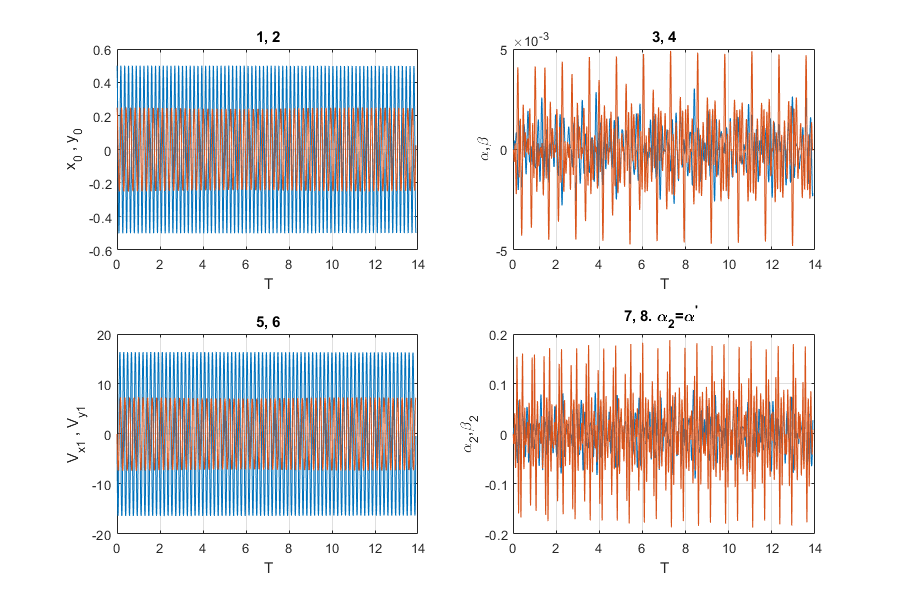

    %clear R, P, Qv
    options = [ ];
    %Загружаем нужные параметры в вектор параметров для передачи в решатель
     par=[Px_dim, Py_dim, Ax_dim, Ay_dim, Mx_dim, ...
     My_dim, Bx_dim, By_dim, p_dim, e_dim,...
     omega_dim, gamma_dim, P1, omega_square, Pk, ...
     i0_dim, iax_dim, iay_dim, ibx_dim, iby_dim,...
     delta_dim, P2, a1_dim, a2_dim];  
   % optinos = odeset('AbsTol', 1e-2, 'RelTol', 1e-3);
%     St=(2*pi)/w; %Масштаб времени отнесенный к угловой частоте омега
    Tend=tend/St;

    [T, X] = ode23s(@ODE_MAGLEV_4DOF, [ t0, Tend] , x0, options, par,C,Hs,G,Hd);
%     Sw=1/St;
%    [T, X] = ode23s(@ODE_MAGLEV_4DOF, [ t0, tend] , x0, options, par,C,Hs,G,Hd );
%      [F] = Force_4DOF(T,par,x0(1),x0(2),x0(3),x0(4)) % Силы
%      Amplitude (nuNum) = AmplitudeDef4DOF(X(:,1)); % Амплитуды перемещений по 1-ой DOF  
%       Amplitude (nuNum, aNum) = AmplitudeDef4DOF(X(:,1)); % Амплитуды перемещений    
%     Amplitude =  AmplitudeDef4DOF(X(:,3));
%     figure
%     plot(T, Amplitude)
%     title('График амплитуд')
%     xlabel('T')
%     ylabel('A')
%             FigurePlotterPhase (X(:,1), X(:, 2), omega_dim)
%             title(str{parNum})
%   Переопределение полученных данных
    x_0=X(:,1);
    y_0=X(:,2);
    alpha=X(:,3);
    beta=X(:,4);
    Vx=X(:,5);
    Vy=X(:,6);
    omega1=X(:,7);
    omega2=X(:,8);
    
%  Обезразмеривание
%     x_0= x_0/Sx;
%     y_0= y_0*Sx;
%     Vx= Vx/Sx;
%     Vy= Vy/Sx;
%     alpha=alpha/Sbeta;
%     beta=beta/Sbeta;
%     omega1=omega1/Sw;
%     omega2=omega2/Sw;
    
%     St=(2*pi)/w; %Масштаб времени отнесенный к омега
%     t=T/St;

    figure('Name','Эволюция обобщенных координат','Position', [100 100 900 600]);
    subplot(2,2,1);
    plot(T, x_0, T, y_0)
    title('1, 2')
    xlabel('T')
    ylabel('x_0 , y_0')
    grid('on')
%     axis([0 T -0.0002 0.0002])
    
    subplot(2,2,2);
    plot(T, alpha, T, beta)
    title('3, 4')
    xlabel('T')
    ylabel('\alpha,\beta')
    grid('on')
    
    subplot(2,2,3);
    plot(T, Vx, T, Vy)
    title('5, 6')
    xlabel('T')
    ylabel('V_x_1 , V_y_1')
    grid('on')
    
    subplot(2,2,4);
    plot(T, omega1, T, omega2)
    title('7, 8. \alpha_2=\alpha^'' ')
    xlabel('T')
    ylabel('\alpha_2,\beta_2')
    grid('on')

    
    %АЧХ
    %set freq = 0.1 Hz, изменяем частоту  ищем max amlitude 
    %     ФЧХ
    %set freq = 0.1 Hz, изменяем частоту  ищем фазу
    
        F = Force_4DOF(Tend,par,x0(1),x0(2),x0(3),x0(4));
    %B=F;
    B=[zeros(4,1);F];
 %B=[0 0 0 0; 0 0 0 0; 0 0 0 0; 0 0 0 0; ]
   Pc=ctrb(A,B); %Матрица управляемости
   n=det(Pc);
   if abs(n)<eps
       disp ('Система управляема')
   else
       disp('Система неуправляема')
   end

Система управляема


   Q=obsv(A,C_ss);
      n=det(Pc);
   if abs(n)<eps
       disp ('Система наблюдаема')
   else
       disp('Система ненаблюдаема')
   end

Система управляема


## Готово

disp('Finish.')

Finish.
